# The calculation of sample capacitance

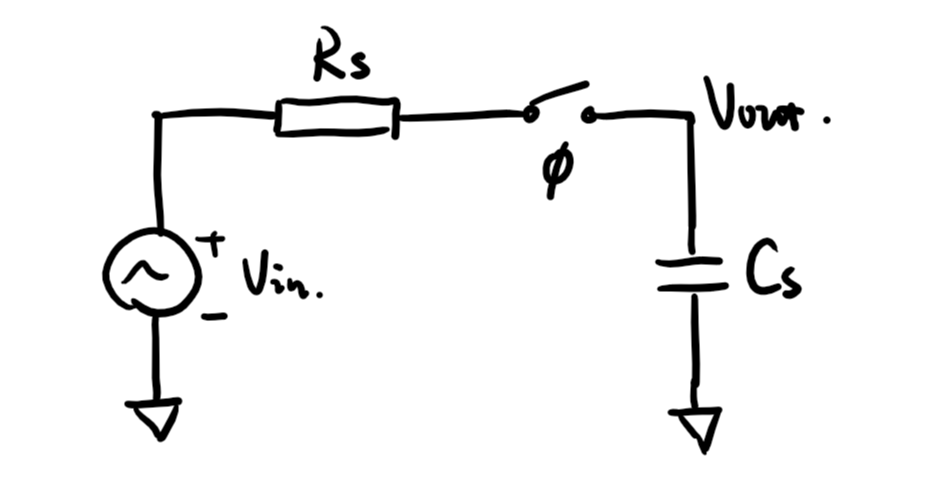

采样的热噪声是决定ADC信噪比的决定性因素，基于以上的采样模型，输出噪声的有效值为：


$$V_{\mathrm{out},\mathrm{rms}} =\sqrt{\;\left(\frac{k_b T}{C_s }\right)},\mathrm{where}\;k_b =1\ldotp 38\times {10}^{-23} \;J/K\;$$


% Clean the previous workspace
clear; clc;


VDD = 3.3;          % Supply voltage
kb = 1.38E-23;      % Boltzmann constant
T = 300;            % Kelvin temperature
N = 17;             % Number of resolution (without sign bit)


## Cap sweep

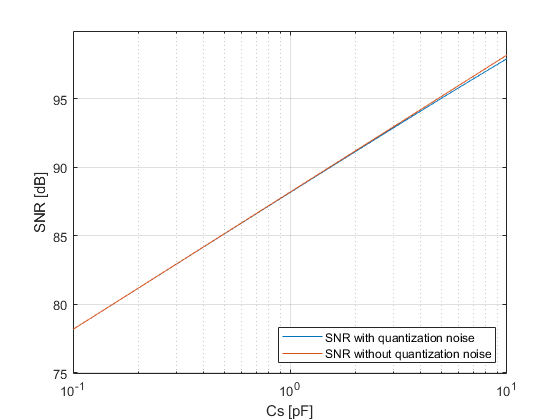

Vin_rms = VDD / sqrt(2);
LSB = VDD / 2^N;
Vn_quan_rms = LSB / sqrt(12);       % quantization noise
c = linspace(0.1,10) * (1E-12);
Vn_ther_rms = sqrt(kb*T./c);        % thermal noise

SNR_quan = Vin_rms^2 ./ (Vn_quan_rms^2 + 2*Vn_ther_rms.^2);
SNR_ther = Vin_rms^2 ./ ( 2*Vn_ther_rms.^2);

figure
semilogx(c./(1E-12), mag2db(SNR_quan) / 2);
hold on;
semilogx(c./(1E-12), mag2db(SNR_ther) / 2);
grid on;
box on;
xlabel("Cs [pF]");
ylabel("SNR [dB]");
legend(["SNR with quantization noise", "SNR without quantization noise"],...
    "Location","southeast");

## Cap Selection

SNR_Target_db = 86

SNR_Target_db = 86

SNR_Target = db2mag(SNR_Target_db*2);
Vn_out = (Vin_rms^2) / SNR_Target;

% with quantization noise
Cs_wi_quan = 2*kb*T / (Vn_out - Vn_quan_rms^2)

Cs_wi_quan = 6.0773e-13


% without quantization noise
Cs_wo_quan =  2*kb*T / (Vn_out)

Cs_wo_quan = 6.0539e-13